# Laboratorio di Automatica (Prova del 07 Luglio 2020)

Riccardo Antonello ([antonello@dei.unipd.it](mail:antonello@dei.unipd.it)) and Luca Schenato ([schenato@dei.unipd.it](mail:schenato@dei.unipd.it)) 

July 07, 2020

Dept. of Information Engineering, University of Padova

## Esercizio 1

In Fig. 1 è mostrato lo schema a blocchi di un sistema di controllo di posizione a tempo discreto per un motore elettrico in corrente continua, dove:

- $P(z)$ è la funzione di trasferimento del motore, da ingresso in tensione $u$ $[V]$ ad uscita in posizione $y\,\mathrm{[rad]}$, ottenuta discretizzando, *con il metodo esatto*, il seguente modello a tempo continuo:


$$P(s) = \frac{Y(s)}{U(s)} = \frac{k_m}{s(T_m\,s + 1)} \quad \text{con} \quad k_m = 5.2\,,\quad T_m = 0.03$$
  

- $C(z)$ è la funzione di trasferimento del controllore, con ingresso l'errore di posizione $e\,\mathrm{[rad]}$ ed uscita la tensione di comando $u_C\,[\mathrm{V}]$, ottenuta discretizzando, *con il metodo di Eulero in Avanti (Forward Euler)*, il seguente controllore a tempo continuo:

 
$$C(s) = \frac{U_C(s)}{E(s)} = \frac{k}{s} \left( \frac{\tau\,s + 1}{\alpha\tau\,s + 1}\right)
\quad \text{con} \quad k\geq 0\,,
\quad \tau = 0.284\,,
\quad \alpha = 0.031$$


Si consideri un periodo di campionamento pari a $T_s = 0.01\,\mathrm{s}$.

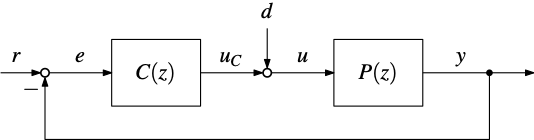

**Figura 1**: Sistema di controllo di posizione a tempo discreto.

Utilizzando *soltanto* le routines del Control System Toolbox (CST), si svolgano i seguenti punti:

1)  Tracciare il luogo delle radici del sistema, al variare del guadagno $k \geq 0$ del controllore.

*Soluzione*.

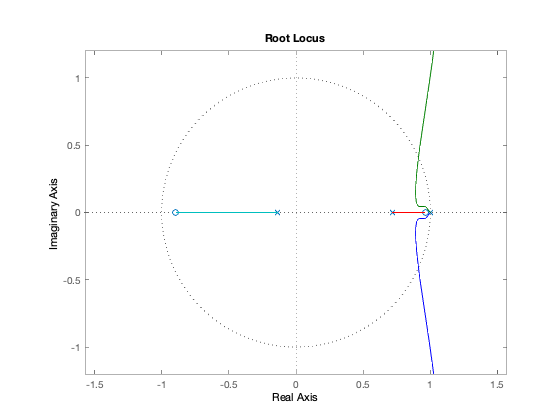

%    plant tf
km = 5.2;
Tm = 0.03;
Ts = 0.01;
sysP = tf(km, [Tm, 1, 0]);
sysP = c2d(sysP, Ts, 'zoh');

%   controller tf
tau = 0.284;
a = 0.031;
z = tf('z', Ts);
s = (z-1)/Ts;
sysC = (1/s) * (tau*s+1)/(a*tau*s+1);

%   loop tf
sysL = minreal(sysP*sysC);

%   root locus
figure;
rlocus(sysL);
axis(1.2 * [-1,1,-1,1]);
axis equal;

2)  Determinare per quali valori del guadagno $k \geq 0$ del controllore il sistema in catena chiusa è BIBO stabile.

*Soluzione*.

%   critical gain (gain margin)
Gm = margin(sysL)

Gm = 46.8088

Il sistema in catena chiusa è BIBO stabile per $0 \leq k \leq 46.836$.

3) Si imposti il guadagno del controllore ad un valore pari a $k=\bar{k}/2$, dove $\bar{k}$ è il massimo guadagno superato il quale il sistema di controllo in catena chiusa diventa instabile (guadagno critico). Con tale valore di guadagno, calcolare i poli del del sistema in catena chiusa, e mostrarli sul luogo delle radici tracciato al punto 1.

*Soluzione*.

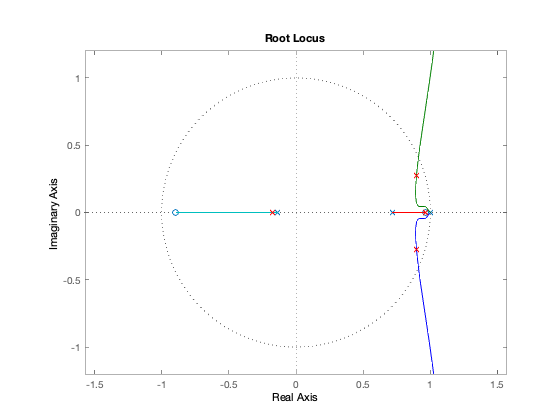

%   controller gain
k = Gm/2;

%   controller tf
sysC1 = k*sysC;

%   loop tf
sysL1 = sysC1*sysP;

%   closed-loop tf
sysT1 = feedback(sysL1,1);

%   closed-loop poles
p = pole(sysT1);

%   plot closed-loop poles
hold on;
plot(p, 'rx');

4) Con il valore di guadagno $k$ impostato al punto 3, determinare la risposta al gradino unitario del sistema in catena chiusa, da riferimento $r$ ad uscita $y$, e mostrarla in un grafico. Determinare inoltre sovraelongazione percentuale e tempo di assestamento al $5\%$.

*Soluzione*.

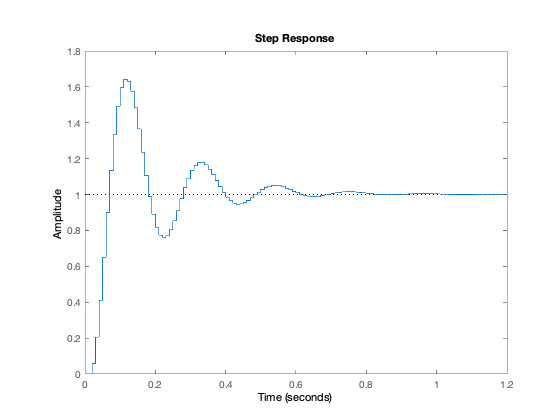

%   step response
figure;
step(sysT1);


%   step response info
stepinfo(sysT1, 'SettlingTimeThreshold', 0.05);
fprintf('Overshoot: %2.4f %%\n', info.Overshoot);

Overshoot: 64.0468 %


fprintf('Settling time: %2.4f s\n', info.SettlingTime);

Settling time: 0.5500 s
